clear
addpath(genpath('src'));

Generation of additive spatially-correlated noise (ASCN)

nsigma = 15;
gsigma = 1;
n = 512;

F = normrnd(0,nsigma,[n n]);
[x,y] = meshgrid(-n/2:n/2-1,-n/2:n/2-1);
G = exp(-pi*(x.^2 + y.^2)./(2*gsigma^2));
g = fftshift(fft2(G));
f = fftshift(fft2(F));
s = g.*f;
S = ifft2(ifftshift(s));
C = std(F(:))*S/std(S(:));

% Or simply use the function to generate ASCN:
% C = ascn2D_fft_gen(normrnd(0,nsigma,[n n]), gsigma);

DCT_NPS = dct2Dnps_add_est(C,dctmtx(8));

Info about ASCN realization

disp(['SD of AWGN: ' num2str(std(F(:)))])

SD of AWGN: 15.0148


disp(['SD of ASCN: ' num2str(std(S(:)))])

SD of ASCN: 16.3101


disp(['Corrected SD of ASCN: ' num2str(std(C(:)))])

Corrected SD of ASCN: 15.0148


disp('Normalized DCT spectrum:')

Normalized DCT spectrum:


disp(DCT_NPS)

         0    1.6819    1.5753    1.4126    1.2239    1.0418    0.8922    0.7927
    1.6729    1.5798    1.4754    1.3240    1.1474    0.9815    0.8452    0.7518
    1.5644    1.4803    1.3849    1.2406    1.0772    0.9240    0.7916    0.7027
    1.4072    1.3306    1.2427    1.1152    0.9739    0.8307    0.7084    0.6325
    1.2285    1.1618    1.0819    0.9726    0.8508    0.7257    0.6194    0.5517
    1.0521    0.9939    0.9261    0.8351    0.7309    0.6269    0.5335    0.4711
    0.8979    0.8462    0.7877    0.7125    0.6251    0.5346    0.4548    0.4031
    0.7969    0.7494    0.6993    0.6290    0.5530    0.4742    0.4010    0.3557



Representation of AWGN realization

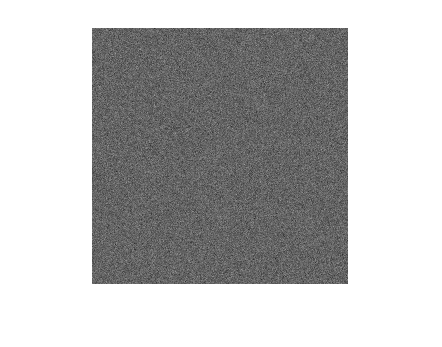

figure;
imshow(uint8(F(1:256,1:256)+100));

Histogram of AWGN realization

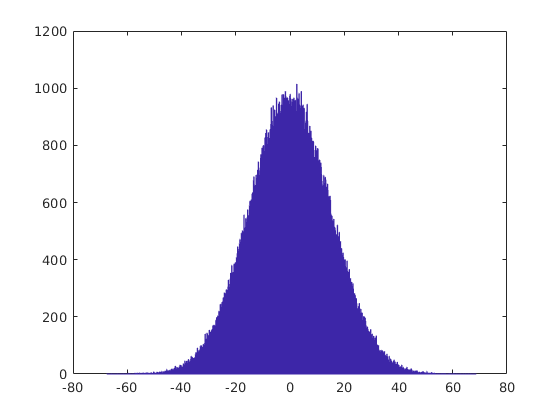

figure;
hist(F(:),1000);

FFT spectrum (shifted - quadrants are replaced) of AWGN realization

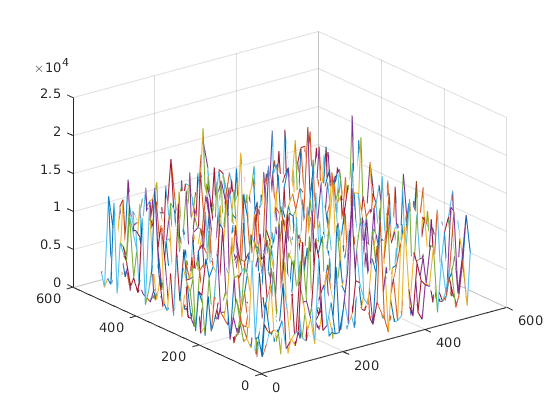

figure;
mesh(1:10:n,1:10:n,abs(f(1:10:end,1:10:end)));
colormap lines

FFT spectrum (shifted - quadrants are replaced) of gaussian weight function

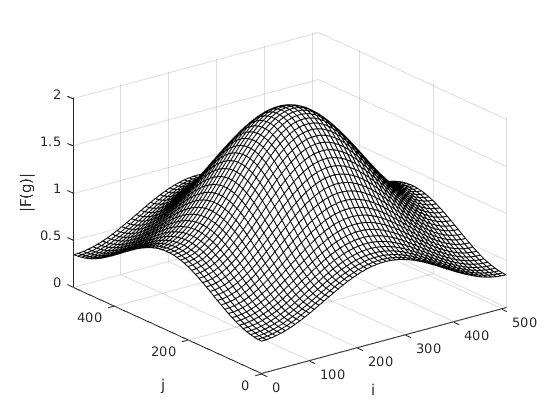

figure;
mesh(1:10:n,1:10:n,abs(g(1:10:end,1:10:end)));
colormap ([0 0 0]) %lines
xlabel('i');
ylabel('j');
zlabel('|F(g)|');
xlim([0 512])
ylim([0 512])

FFT spectrum of product (weighted spectrum of ASCN realization)

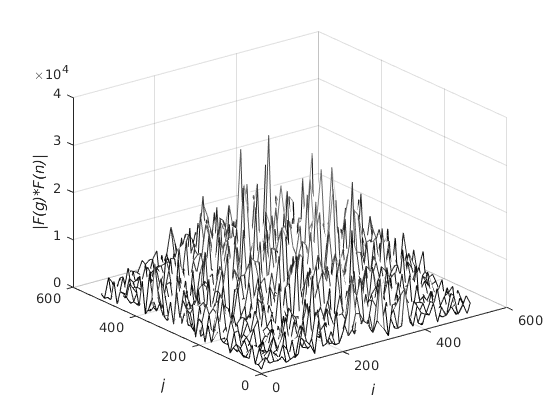

figure;
mesh(1:10:n,1:10:n,abs(s(1:10:end,1:10:end)));
colormap gray %lines
xlabel('\iti');
ylabel('\itj');
zlabel('|\itF(g)*F(n)|');

Histogram of ASCN realization 

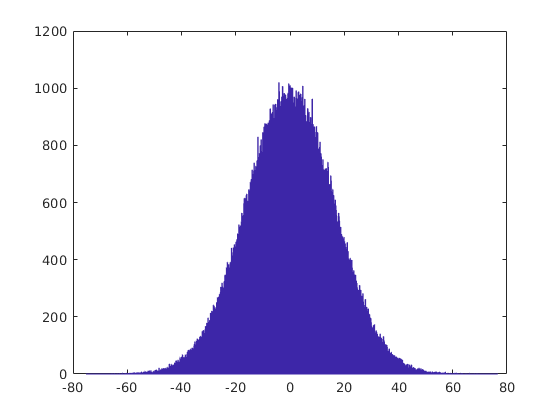

figure;
hist(S(:),1000);

Representation of ASCGN

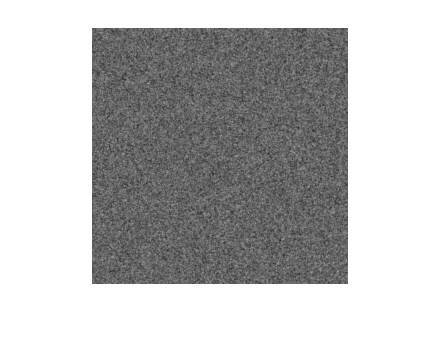

figure;
imshow(uint8(C(1:256,1:256)+100));

Histogram of ASCN realization with corrected STD

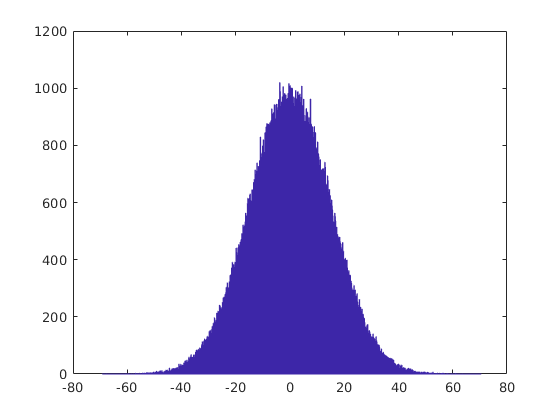

figure;
hist(C(:),1000);

Bar graph of 8*8 block DCT normalized ASCN spectrum

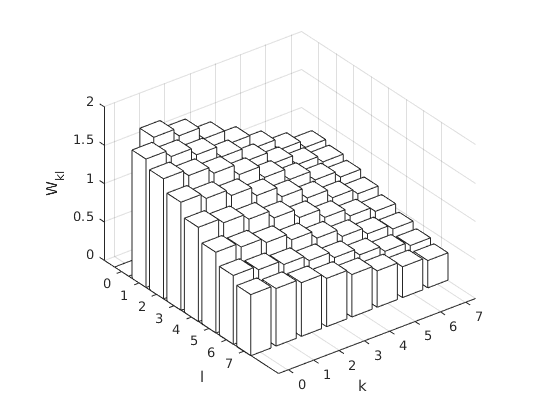

figure;
bar3(DCT_NPS);
set(gca,'XTickLabel',{'0','1','2','3','4','5','6','7'},...
    'YTickLabel',{'0','1','2','3','4','5','6','7'});
xlabel('k');
ylabel('l');
zlabel('W_{kl}');
colormap white %hot